#### Voorbeeldoefening

#### Grafisch Model Doorgeefcircuit

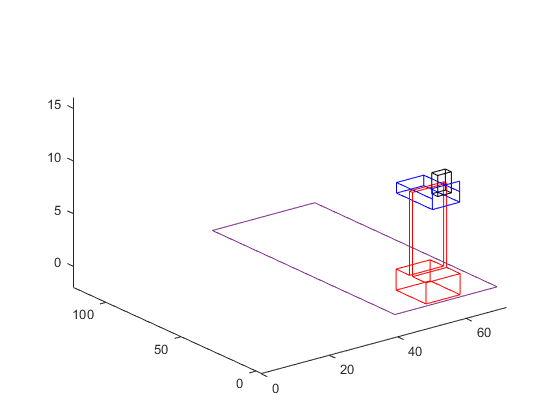

% Basisvorm basis + wip bestaande uit 6 + 4 vlakken,
% achterste vlak van auto "begint" op (50,0,0) want tafereel is yz-vlak:
Punten_Basis_1 = [50 50 50  50  50  50  50  50 50
                   0  0  9   9  11  11  20  20  0
                   0  2  2  10  10   2   2   0  0];
Punten_Basis_2 = [60 60 60 60 60 60 60 60 60
                   0  0  9  9 11 11 20 20  0
                   0  2  2 10 10  2  2  0  0];
Punten_Basis_3 = [50 50 60 60 50
                  0   0  0  0  0
                  0   2  2  0  0];
Punten_Basis_4 = [ 50  50 60 60  50
                   20  20 20 20  20
                   0    2  2  0   0];
Punten_Basis_5 = [50 60 60  50 50
                  9  9   9   9  9
                  2  2  10  10  2];
Punten_Basis_6 = [50 60 60   50   50
                  11 11 11   11   11
                   2  2 10   10   2];

plot3(Punten_Basis_1(1,:),Punten_Basis_1(2,:),Punten_Basis_1(3,:),'r');
hold on
plot3(Punten_Basis_2(1,:),Punten_Basis_2(2,:),Punten_Basis_2(3,:),'r');
plot3(Punten_Basis_3(1,:),Punten_Basis_3(2,:),Punten_Basis_3(3,:),'r');
plot3(Punten_Basis_4(1,:),Punten_Basis_4(2,:),Punten_Basis_4(3,:),'r');
plot3(Punten_Basis_5(1,:),Punten_Basis_5(2,:),Punten_Basis_5(3,:),'r');
plot3(Punten_Basis_6(1,:),Punten_Basis_6(2,:),Punten_Basis_6(3,:),'r');

Punten_Wip_1 = [51   51   51  51  51
                -2   -2   22  22  -2
                 9   10   10   9   9];
Punten_Wip_2 = [59  59  59 59  59
                -2  -2  22 22  -2
                 9  10  10  9   9];
Punten_Wip_3 = [51 59  59   51  51
                -2 -2  -2   -2  -2
                 9  9  11   11  9];
Punten_Wip_4 = [51 59  59   51  51
                22 22  22   22  22 
                 9  9  10   10   9];
plot3(Punten_Wip_1(1,:),Punten_Wip_1(2,:),Punten_Wip_1(3,:),'b');
plot3(Punten_Wip_2(1,:),Punten_Wip_2(2,:),Punten_Wip_2(3,:),'b');
plot3(Punten_Wip_3(1,:),Punten_Wip_3(2,:),Punten_Wip_3(3,:),'b');
plot3(Punten_Wip_4(1,:),Punten_Wip_4(2,:),Punten_Wip_4(3,:),'b');

% MDF-plaat bestaande uit 1 vlak:
Punten_Plaat = [40 70  70  40  40
                -2 -2 120 120  -2
                 0  0   0   0   0];
plot3(Punten_Plaat(1,:),Punten_Plaat(2,:),Punten_Plaat(3,:));

% "Balletje" bestaande uit 4 vlakken:
Punten_Bal_1 = [53 53 53 53 53 
                -1 -1 3  3  -1
                10 12 12 10 10];
Punten_Bal_2 = [57 57 57 57 57 
                -1 -1 3  3  -1
                10 12 12 10 10];
Punten_Bal_3 = [53 57 57 53 53 
                -1 -1 3  3  -1
                10 10 10 10 10];
Punten_Bal_4 = [53 57 57 53 53 
                -1 -1 3  3  -1
                12 12 12 12 12];


plot3(Punten_Bal_1(1,:),Punten_Bal_1(2,:),Punten_Bal_1(3,:),'k');
plot3(Punten_Bal_2(1,:),Punten_Bal_2(2,:),Punten_Bal_2(3,:),'k');
plot3(Punten_Bal_3(1,:),Punten_Bal_3(2,:),Punten_Bal_3(3,:),'k');
plot3(Punten_Bal_4(1,:),Punten_Bal_4(2,:),Punten_Bal_4(3,:),'k');

axis([0 72 -4 122 -2 16]);
hold off

% Omzetten naar homogene coördinaten:
Punten_Basis_1_H = Punten_Basis_1;
Punten_Basis_1_H(4,:) = 1;
Punten_Basis_2_H = Punten_Basis_2;
Punten_Basis_2_H(4,:) = 1;
Punten_Basis_3_H = Punten_Basis_3;
Punten_Basis_3_H(4,:) = 1;
Punten_Basis_4_H = Punten_Basis_4;
Punten_Basis_4_H(4,:) = 1;
Punten_Basis_5_H = Punten_Basis_5;
Punten_Basis_5_H(4,:) = 1;
Punten_Basis_6_H = Punten_Basis_6;
Punten_Basis_6_H(4,:) = 1;

Punten_Wip_1_H = Punten_Wip_1;
Punten_Wip_1_H(4,:) = 1;
Punten_Wip_2_H = Punten_Wip_2;
Punten_Wip_2_H(4,:) = 1;
Punten_Wip_3_H = Punten_Wip_3;
Punten_Wip_3_H(4,:) = 1;
Punten_Wip_4_H = Punten_Wip_4;
Punten_Wip_4_H(4,:) = 1;

Punten_Plaat_H = Punten_Plaat;
Punten_Plaat_H(4,:) = 1;

Punten_Bal_1_H = Punten_Bal_1;
Punten_Bal_1_H(4,:) = 1;
Punten_Bal_2_H = Punten_Bal_2;
Punten_Bal_2_H(4,:) = 1;
Punten_Bal_3_H = Punten_Bal_3;
Punten_Bal_3_H(4,:) = 1;
Punten_Bal_4_H = Punten_Bal_4;
Punten_Bal_4_H(4,:) = 1;

% "Startrotatie" rond x-as naar eigenlijke beginpositie van wip en bal (+10°)
% Eerst alles verplaatsen naar x-as en dan terug, volgens middelpunt van de
% rotatie (as waarop wip draait).
Rotatie_Start = [1             0               0  0
                 0 cos(10*pi/180) -sin(10*pi/180) 0
                 0 sin(10*pi/180)  cos(10*pi/180) 0
                 0             0               0  1];
Translatie_NaarAs_Start = [1 0 0    0
                           0 1 0  -10
                           0 0 1 -9.5
                           0 0 0    1];
Translatie_VanAs_Start = [1 0 0   0
                          0 1 0  10
                          0 0 1 9.5
                          0 0 0   1];

Punten_Wip_1_H = Translatie_VanAs_Start*Rotatie_Start*Translatie_NaarAs_Start*Punten_Wip_1_H;
Punten_Wip_2_H = Translatie_VanAs_Start*Rotatie_Start*Translatie_NaarAs_Start*Punten_Wip_2_H;
Punten_Wip_3_H = Translatie_VanAs_Start*Rotatie_Start*Translatie_NaarAs_Start*Punten_Wip_3_H;
Punten_Wip_4_H = Translatie_VanAs_Start*Rotatie_Start*Translatie_NaarAs_Start*Punten_Wip_4_H;



Punten_Bal_1_H = Translatie_VanAs_Start*Rotatie_Start*Translatie_NaarAs_Start*Punten_Bal_1_H;
Punten_Bal_2_H = Translatie_VanAs_Start*Rotatie_Start*Translatie_NaarAs_Start*Punten_Bal_2_H;
Punten_Bal_3_H = Translatie_VanAs_Start*Rotatie_Start*Translatie_NaarAs_Start*Punten_Bal_3_H;
Punten_Bal_4_H = Translatie_VanAs_Start*Rotatie_Start*Translatie_NaarAs_Start*Punten_Bal_4_H;

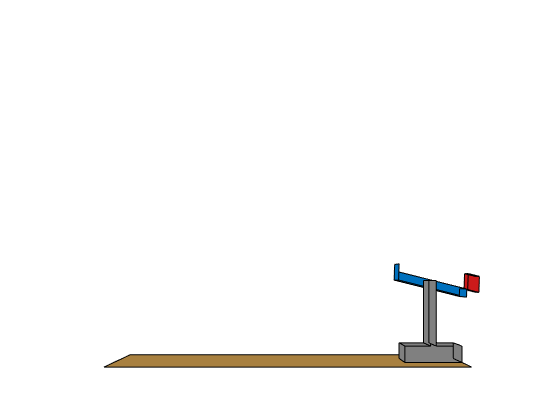

% Centrale projectie op yz-vlak
% normaalvector n, punt in vlak (hier oorsprong) B:
n = [1;0;0];
B = [0;0;0];
% vlakbepalende vector nn = [nx; ny; nz; D] waarbij D = n.(O-0) = 0:
nn = [1;0;0;0];
% oog V op (250, 59, 20), dus 
% vijf zo ver van het tafereel als de auto,
% op het midden van het traject van de beweging, en
% ongeveer ten hoogte van de wip:
V = [250;59;10;1];
% projectiematrix M:
M = [(V*nn') - dot(nn, V)*eye(4)];

% For-lus om de totale beweging in 120 delen (+ 10 delen rollend balletje) te doen om met 60fps een
% bewegingstijd van 2s (ongeveer hoe lang de reële beweging duurt) te bekomen:
for i = 1:130
    % In het eerste deel van de animatie beweegt de basis + wip
    if (i <= 120)
        % Totale translatie (y + 100) in 120 delen te doen (2s, 60fps).
        % Stapsgewijze translatiematrix:
        Translatie_Vooruit_Stap = [1 0 0   0
                           0 1 0 5/6
                           0 0 1   0
                           0 0 0   1];
        % Rotatie rond x-as naar eindpositie van wip+bal.
        % Totale rotatie (-15°) in 120 delen te doen (2s, 60fps).
        % Reële rotatie is iets groter (-35°) maar geeft vertekend beeld na
        % projectie.
        % Stapsgewijze rotatiematrix:
        Rotatie_Stap = [1                    0                      0  0
                        0 cos((-15*pi/180)/120) -sin((-15*pi/180)/120) 0
                        0 sin((-15*pi/180)/120)  cos((-15*pi/180)/120) 0
                        0                    0                      0  1];
        % Eerst alles verplaatsen naar x-as en dan terug, volgens middelpunt van de
        % rotatie (as waarop wip draait) dat nu ook mee verplaatst met de
        % translatie die gebeurt door Translatie_Stap:
        Translatie_NaarAs_Stap = [1 0 0             0
                                  0 1 0  -(10 + i*5/6)
                                  0 0 1          -9.5
                                  0 0 0             1];
        Translatie_VanAs_Stap = [1 0 0             0
                                  0 1 0  (10 + i*5/6)
                                  0 0 1          9.5
                                  0 0 0            1];
    
        % Bij elke stap voeren we de translatie uit die het vooruitrijden
        % voorstelt, vervolgens transleren we enkel de te-roteren onderdelen
        % naar de x-as, roteren we ze hier, en transleren we ze terug:
        Punten_Basis_1_H = Translatie_Vooruit_Stap*Punten_Basis_1_H;
        Punten_Basis_2_H = Translatie_Vooruit_Stap*Punten_Basis_2_H;
        Punten_Basis_3_H = Translatie_Vooruit_Stap*Punten_Basis_3_H;
        Punten_Basis_4_H = Translatie_Vooruit_Stap*Punten_Basis_4_H;
        Punten_Basis_5_H = Translatie_Vooruit_Stap*Punten_Basis_5_H;
        Punten_Basis_6_H = Translatie_Vooruit_Stap*Punten_Basis_6_H;
        
        Punten_Wip_1_H = Translatie_VanAs_Stap*Rotatie_Stap*Translatie_NaarAs_Stap*Translatie_Vooruit_Stap*Punten_Wip_1_H;
        Punten_Wip_2_H = Translatie_VanAs_Stap*Rotatie_Stap*Translatie_NaarAs_Stap*Translatie_Vooruit_Stap*Punten_Wip_2_H;
        Punten_Wip_3_H = Translatie_VanAs_Stap*Rotatie_Stap*Translatie_NaarAs_Stap*Translatie_Vooruit_Stap*Punten_Wip_3_H;
        Punten_Wip_4_H = Translatie_VanAs_Stap*Rotatie_Stap*Translatie_NaarAs_Stap*Translatie_Vooruit_Stap*Punten_Wip_4_H;
        
        Punten_Bal_1_H = Translatie_VanAs_Stap*Rotatie_Stap*Translatie_NaarAs_Stap*Translatie_Vooruit_Stap*Punten_Bal_1_H;
        Punten_Bal_2_H = Translatie_VanAs_Stap*Rotatie_Stap*Translatie_NaarAs_Stap*Translatie_Vooruit_Stap*Punten_Bal_2_H;
        Punten_Bal_3_H = Translatie_VanAs_Stap*Rotatie_Stap*Translatie_NaarAs_Stap*Translatie_Vooruit_Stap*Punten_Bal_3_H;
        Punten_Bal_4_H = Translatie_VanAs_Stap*Rotatie_Stap*Translatie_NaarAs_Stap*Translatie_Vooruit_Stap*Punten_Bal_4_H;
    % In het laatste deel van de animatie rolt het balletje nog wat verder
    else
        % Balletje rolt volgens helling van boven/ondervlak wip in eindstand
        % We moeten dit maar één keer bepalen want wip draait niet meer
        if (i == 121)
            Rol_Y_Stap = (Punten_Wip_1_H(2,3) - Punten_Wip_1_H(2,2)) / 10;
            Rol_Z_Stap = (Punten_Wip_1_H(3,3) - Punten_Wip_1_H(3,2)) / 10;
        end
        Translatie_Rol = [1 0 0          0
                          0 1 0 Rol_Y_Stap
                          0 0 1 Rol_Z_Stap
                          0 0 0          1];
        Punten_Bal_1_H = Translatie_Rol*Punten_Bal_1_H;
        Punten_Bal_2_H = Translatie_Rol*Punten_Bal_2_H;
        Punten_Bal_3_H = Translatie_Rol*Punten_Bal_3_H;
        Punten_Bal_4_H = Translatie_Rol*Punten_Bal_4_H;
    end
    % Omzetten naar geprojecteerde homogene coördinaten
    % Eerst projectiematrix toepassen
    Punten_Basis_1_hP = M*Punten_Basis_1_H;
    Punten_Basis_2_hP = M*Punten_Basis_2_H;
    Punten_Basis_3_hP = M*Punten_Basis_3_H;
    Punten_Basis_4_hP = M*Punten_Basis_4_H;
    Punten_Basis_5_hP = M*Punten_Basis_5_H;
    Punten_Basis_6_hP = M*Punten_Basis_6_H;
    
    Punten_Wip_1_hP = M*Punten_Wip_1_H;
    Punten_Wip_2_hP = M*Punten_Wip_2_H;
    Punten_Wip_3_hP = M*Punten_Wip_3_H;
    Punten_Wip_4_hP = M*Punten_Wip_4_H;
    
    Punten_Plaat_hP = M*Punten_Plaat_H;
    
    Punten_Bal_1_hP = M*Punten_Bal_1_H;
    Punten_Bal_2_hP = M*Punten_Bal_2_H;
    Punten_Bal_3_hP = M*Punten_Bal_3_H;
    Punten_Bal_4_hP = M*Punten_Bal_4_H;
    
    % Dan alles herschalen zodat homogene coördinaat == 1
    Punten_Basis_1_hP = Punten_Basis_1_hP ./ Punten_Basis_1_hP(4,:);
    Punten_Basis_2_hP = Punten_Basis_2_hP ./ Punten_Basis_2_hP(4,:);
    Punten_Basis_3_hP = Punten_Basis_3_hP ./ Punten_Basis_3_hP(4,:);
    Punten_Basis_4_hP = Punten_Basis_4_hP ./ Punten_Basis_4_hP(4,:);
    Punten_Basis_5_hP = Punten_Basis_5_hP ./ Punten_Basis_5_hP(4,:);
    Punten_Basis_6_hP = Punten_Basis_6_hP ./ Punten_Basis_6_hP(4,:);
    
    Punten_Wip_1_hP = Punten_Wip_1_hP ./ Punten_Wip_1_hP(4,:);
    Punten_Wip_2_hP = Punten_Wip_2_hP ./ Punten_Wip_2_hP(4,:);
    Punten_Wip_3_hP = Punten_Wip_3_hP ./ Punten_Wip_3_hP(4,:);
    Punten_Wip_4_hP = Punten_Wip_4_hP ./ Punten_Wip_4_hP(4,:);
    
    Punten_Plaat_hP = Punten_Plaat_hP ./ Punten_Plaat_hP(4,:);
    
    Punten_Bal_1_hP = Punten_Bal_1_hP ./ Punten_Bal_1_hP(4,:);
    Punten_Bal_2_hP = Punten_Bal_2_hP ./ Punten_Bal_2_hP(4,:);
    Punten_Bal_3_hP = Punten_Bal_3_hP ./ Punten_Bal_3_hP(4,:);
    Punten_Bal_4_hP = Punten_Bal_4_hP ./ Punten_Bal_4_hP(4,:);
    
    % Plot van centrale projectie op yz-vlak
    % polyshape() gooit een paar warnings die de executie niet negatief
    % beïnvloeden, waarschijnlijk door overlap tussen hoekpunten van
    % verschillende vlakken. Het leek ons niet nodig om hiervoor al onze
    % vertexmatrices te veranderen en bovendien zijn we niet zeker of we
    % hiermee de warnings wegkrijgen.
    warning('off', 'MATLAB:polyshape:repairedBySimplify')
    warning('off', 'MATLAB:polyshape:boolOperationFailed')
    % polyshape() verwacht coördinaten te lezen in rijen van twee ipv
    % kolommen van twee zoals in onze matrices, dus transpose().
    plot(polyshape(transpose(Punten_Plaat_hP(2:3,:))), 'FaceColor', [0.66 0.5 0.25], 'FaceAlpha', 1);
    hold on

    plot(polyshape(transpose(Punten_Bal_1_hP(2:3,:))), 'FaceColor', [0.8 0.1 0.1], 'FaceAlpha', 1);
    plot(polyshape(transpose(Punten_Bal_2_hP(2:3,:))), 'FaceColor', [0.8 0.1 0.1], 'FaceAlpha', 1);
    plot(polyshape(transpose(Punten_Bal_3_hP(2:3,:))), 'FaceColor', [0.8 0.1 0.1], 'FaceAlpha', 1);
    plot(polyshape(transpose(Punten_Bal_4_hP(2:3,:))), 'FaceColor', [0.8 0.1 0.1], 'FaceAlpha', 1);

    plot(polyshape(transpose(Punten_Wip_1_hP(2:3,:))), 'FaceColor', [0 0.44 0.74], 'FaceAlpha', 1);
    plot(polyshape(transpose(Punten_Wip_2_hP(2:3,:))), 'FaceColor', [0 0.44 0.74], 'FaceAlpha', 1);
    plot(polyshape(transpose(Punten_Wip_3_hP(2:3,:))), 'FaceColor', [0 0.44 0.74], 'FaceAlpha', 1);
    plot(polyshape(transpose(Punten_Wip_4_hP(2:3,:))), 'FaceColor', [0 0.44 0.74], 'FaceAlpha', 1);

    plot(polyshape(transpose(Punten_Basis_1_hP(2:3,:))), 'FaceColor', [0.5 0.5 0.5], 'FaceAlpha', 1);
    plot(polyshape(transpose(Punten_Basis_2_hP(2:3,:))), 'FaceColor', [0.5 0.5 0.5], 'FaceAlpha', 1);
    plot(polyshape(transpose(Punten_Basis_3_hP(2:3,:))), 'FaceColor', [0.5 0.5 0.5], 'FaceAlpha', 1);
    plot(polyshape(transpose(Punten_Basis_4_hP(2:3,:))), 'FaceColor', [0.5 0.5 0.5], 'FaceAlpha', 1);
    plot(polyshape(transpose(Punten_Basis_5_hP(2:3,:))), 'FaceColor', [0.5 0.5 0.5], 'FaceAlpha', 1);
    plot(polyshape(transpose(Punten_Basis_6_hP(2:3,:))), 'FaceColor', [0.5 0.5 0.5], 'FaceAlpha', 1);
    
    axis([-40 160 -5 50])
    axis('off');
    hold off
    % Opteren om met pause() tussen elke iteratie te werken,
    % daarna export-functie binnen MATLAB van geänimeerde figuur:
    pause(1/60);
end